# The Tacoma Narrows Bridge Disaster

## Task 1

The angle that the road makes with the horizontal *θ*(t)  can be determined by solving the following second-order ODE:

d2*θ*dt2=−0.01d*θ*dt−2.4cos*θ*sin*θ*+0.05sin(1.3t)

with initial conditions

*θ*(0)=1.2 radians

d*θ*dt(0)=*ω*(0)=0 rad/s

Task

Use the following steps to solve the second-order ODE for the angular position of the oscillating road. 

1. Rewrite the second-order ODE as a system of two first-order ODEs. Just as you used position (`y`) and velocity (`v`) in the previous section, use variables for the angular position (`Theta`) and angular velocity (`Omega`). 

2. Write a local function named `tacomaNarrows` at the bottom of the script to reflect the system of first-order ODEs. 

3. Set the time interval `tRange` and initial conditions vector `Y0`. Your time interval should range from 0 to 1000 seconds. 

4. Solve the differential equation using `ode45`. Save the output to variables `tSol` and `YSol`.   

Find and plot the road oscillations for the first 1000 seconds of motion.

*Remember to define your ODE function at the bottom of the script. *

tRange=[0 1000]

tRange =            0        1000


Y0=[1.2;0]

Y0 =     1.2000
         0


[tSol,YSol]=ode45(@tacomaNarrows,tRange,Y0)

tSol = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =     1.2000         0
    1.2000   -0.0001
    1.2000   -0.0001
    1.2000   -0.0002
    1.2000   -0.0002
    1.2000   -0.0005
    1.2000   -0.0007
    1.2000   -0.0010
    1.2000   -0.0012
    1.2000   -0.0025


## Task 2

Extract the first column of `YSol` and define it as `Theta`. Convert `Theta` from radians to degrees by multiplying by 

180/*π *and storing the result back in `Theta`. Then, plot `Theta` vs. `tSol` and add an appropriate label the vertical axis such as `"Road Angle"`.

Theta=YSol(:,1)

Theta =     1.2000
    1.2000
    1.2000
    1.2000
    1.2000
    1.2000
    1.2000
    1.2000
    1.2000
    1.2000


Theta=Theta.*(180/pi)

Theta =    68.7549
   68.7549
   68.7549
   68.7549
   68.7549
   68.7549
   68.7549
   68.7549
   68.7549
   68.7547


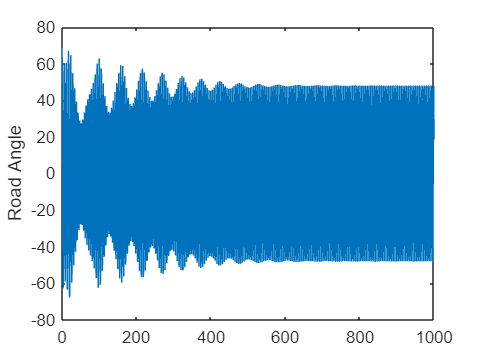

plot(tSol,Theta)
ylabel("Road Angle")

## Task 1 (continued)

Define the ODE function for   

function dYdt=tacomaNarrows(t,Y)
Theta=Y(1);
Omega=Y(2);
dThetadt=Omega;
dOmegadt=-0.01.*Omega-2.4.*cos(Theta).*sin(Theta)+0.05.*sin(1.3.*t);
dYdt=[dThetadt;dOmegadt];
end